# **Chapter 19 Mini Quiz (Q2)**

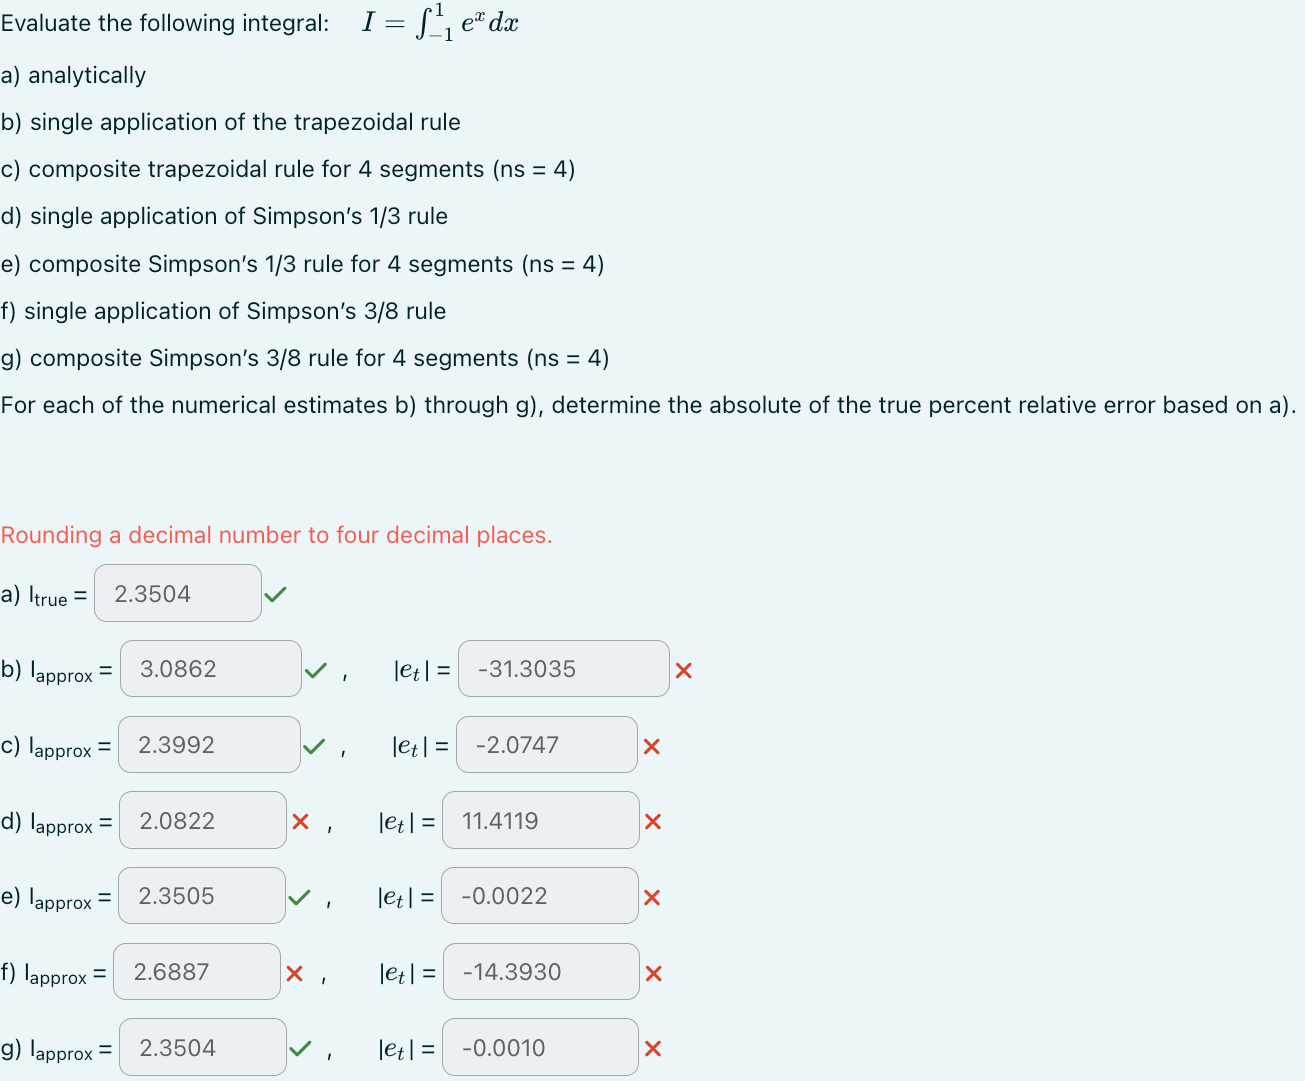

Function

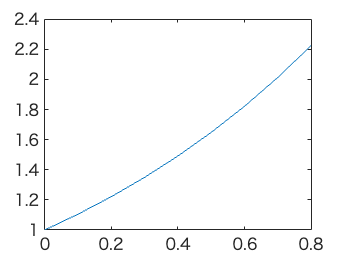

f=@(x) exp(x);
xx = a : 0.1 : b;
yy = f(xx);

plot(xx, yy, '-')

To integrate function from -1 to 1 *(doing analytical integration)*

format short
a = -1;
b = 1;
Itrue = exp(b) - exp(a) % for relative value (this is from `polyint` help page)

Itrue = 2.3504

Plot original function along with trapezoidal rule ns = 1 (single application)

ns = 1

ns = 1

% NEW
I_trap_ns1 = trap(f, a, b, ns)

I_trap_ns1 = 3.0862

err_ns1 = ((Itrue - I_trap_ns1) / Itrue) * 100

err_ns1 = -31.3035

Plot original function along with trapezoidal rule ns = 4

ns = 4

ns = 4

% NEW
I_trap_ns4 = trap(f, a, b, ns)

I_trap_ns4 = 2.3992

err_ns4 = ((Itrue - I_trap_ns4) / Itrue) * 100

err_ns4 = -2.0747

Single application of Simpson’s 1/3 rule (ns = 1)

y = f(x);
% NEW
h = (b - a) / 2

h = 1

I_simpson13_ns1 = (h/3) * (y(1) + 4*y(2) + y(3)) % formula from the slides (page 18)

I_simpson13_ns1 = 2.0822

err_simpson13_ns1 = ((Itrue - I_simpson13_ns1) / Itrue) * 100

err_simpson13_ns1 = 11.4119

# **TODO: VERIFY CODE IN THIS SECTION**

Composite Simpson’s 1/3 rule for 4 segments (ns = 4)

ns = 4

ns = 4

h = (b - a) / (2*ns); % step size
simpson13_ns4 = zeros(1,ns);

for i = 1:ns
    x0 = a + 2*(i-1)*h;
    simpson13_ns4(i) = (h/3)*( ...
        f(x0)        + ...
        4*f(x0 + h)  + ...
        f(x0 + 2*h) );
end

I_simpson13_ns4  = sum(simpson13_ns4)

I_simpson13_ns4 = 2.3505

err_simpson13_ns4 = ((Itrue - I_simpson13_ns4)/Itrue)*100

err_simpson13_ns4 = -0.0022

Single application of Simpson’s 3/8 rule (ns = 1)

y = f(x);

% NEW
h = (b - a) / 3

h = 0.6667

I_simpson38_ns1 = (3*h/8) * (y(1) + 3*y(2) + 3*y(3) + 3*y(4)) % formula from the slides (page 18)

I_simpson38_ns1 = 2.6887

err_simpson38_ns1 = ((Itrue - I_simpson38_ns1) / Itrue) * 100

err_simpson38_ns1 = -14.3930

Composite Simpson’s 3/8 rule for 4 segments (ns = 4)

%% FINISHED CODE — Composite Simpson 3/8 with ns = 4 segments
ns = 4;                                 % number of Simpson-3/8 segments
h  = (b - a)/(3*ns);                    % step size

simpson38_ns4 = zeros(1,ns);
for i = 1:ns
    x0 = a + 3*(i-1)*h;
    simpson38_ns4(i) = (3*h/8)*( ...
        f(x0)          + ...
        3*f(x0 +   h)  + ...
        3*f(x0 + 2*h)  + ...
        f(x0 + 3*h) );
end

I_simpson38_ns4  = sum(simpson38_ns4)

I_simpson38_ns4 = 2.3504

err_simpson38_ns4 = ((Itrue - I_simpson38_ns4)/Itrue)*100

err_simpson38_ns4 = -9.5817e-04

ans = -1.0000e-03